# Pico Control of XR2206

## Objective: 

Control the frequency of an XR2206 function generator using a Raspberry pi (RPi) Pico, and recycling the circuits and Arduino Nano source codes we previously developed in EMEC/PHYS 310 as much as possible

## Methods (Arduino Nano)

### Hardware interfaces

The following circuit was designed for the Nano to control the voltage of the LM317, and our immediate goal is to recycle it with as little modififcation as possible to control the XR2206 frequency.  

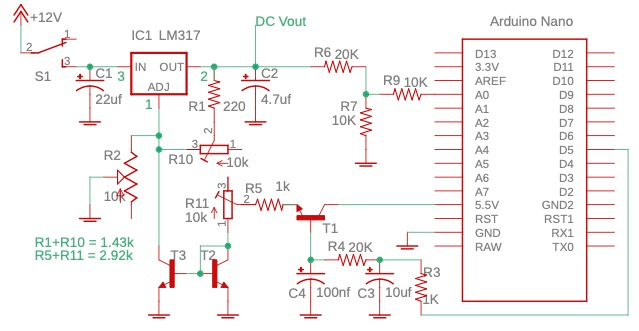

The T3 collector was connected to the XR2206 pin 7 through a 5k reistor R6:

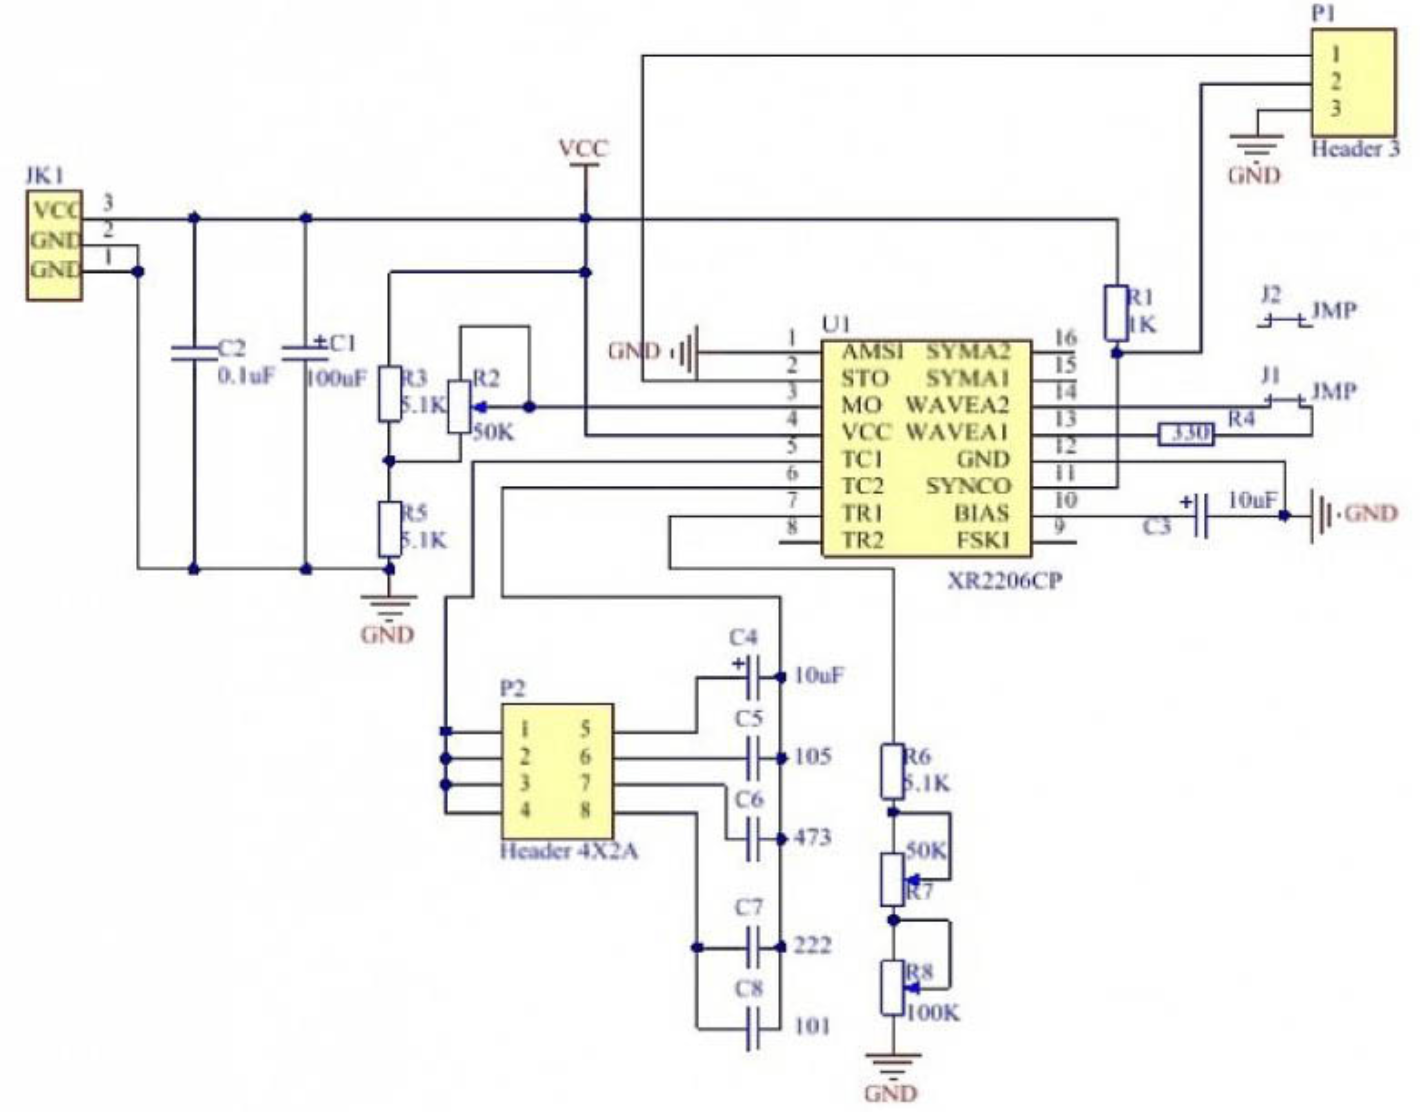

https://www.komitart.ru/uploads/posts/2020-12/1609313048_china-kit-xr2206-generator-schematic.jpg -- I boycot Russia now, but this was the first website I found to snarf a schematic. 

Search the XR2206 datasheet for "sweep" leads to pg. 11, f(Hz) = 320*It(mA)/C(uf) and refers to Fig. 10: 

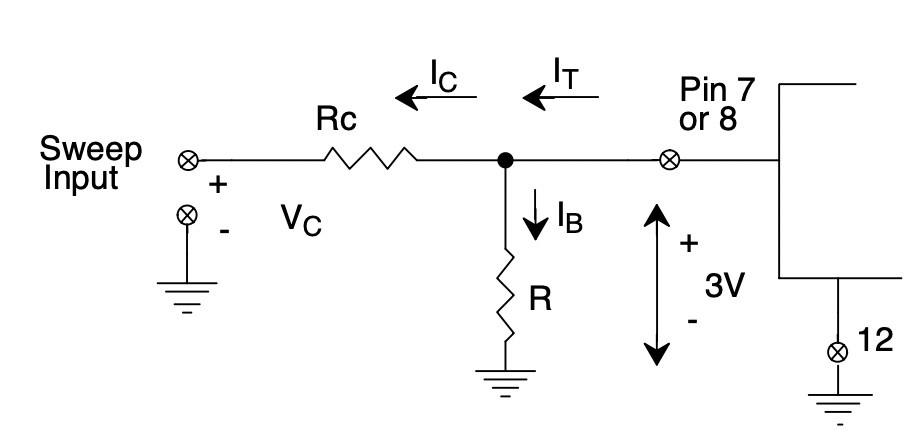 

So in manual operation, It = 3V/(R6+R7+R8), but our current mirror will add a parallel path. What are the approximate ranges of these currents? The manual resistance ranges from 155-5.1kohm, and the current mirror ranges from 0-~4.5V/(R5+R11) -- there's a small Vce drop  on T2 (perhaps ~ 0.2V) and a Vbe ~0.6V drop across T1, starting from D5~ 4.6-5V when pwm = 255. 

fprintf('%.3g < manual It < %.3g mA\n',3 ./[155 5.1])

0.0194 < manual It < 0.588 mA


fprintf('%.3g < mirror It < %.3g mA\n', 0, 4.5/2.92)

0 < mirror It < 1.54 mA


This suggests the mirror should generate higher frequencies that the pot ... but it won't if we connect the mirror to the 5.1k resistor instead of pin 7 directly ... more on that later. 

The following is the result of varying PWM, 

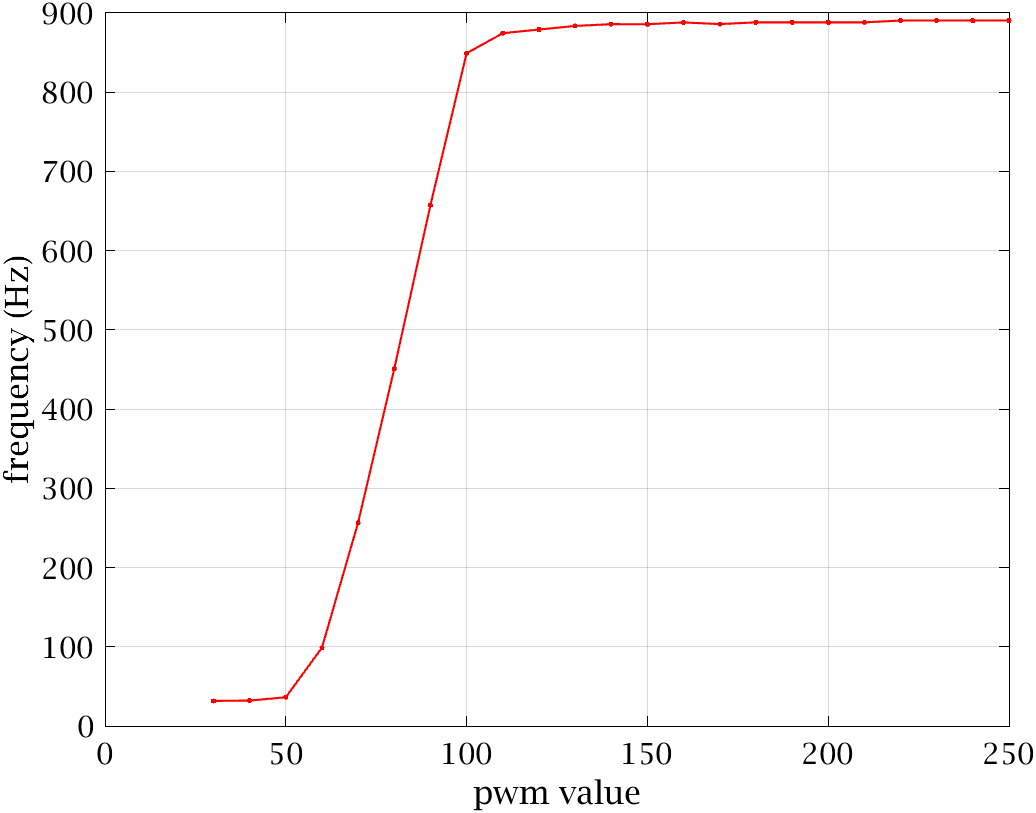

### Programming the Pico

The Pico was programmed with ArduinoController1.ino, which supports the following command set:

%{
/*  ArduinoController1.ino serial command set (originally written to
control an LM317 voltage and an oscilloscope display in Matlab, oscope3.m)
  Arduino control of LM317 voltage and readback supports this command set: 
    p <pwmValue>
    v <volts>
    a -- loop through all pwm
    s <settleTimeMsec>
    r -- read and write buffer of A0 and A1 appended with read time in microseconds
    b -- read and write binary buffer of A0 and A1 appended with read time in microseconds
%}

Setting up the Arduino IDE to program a RPi pico is described elsewhere (Ref). ArduinoController1.ino is also further explained previousl (Ref). 

### Connecting Matlab to RPi Pico 

Matlab initializes the RPi Pico in the identical manner as the Arduino Nano, on my Macbook the last serialportlist entry happens to point to either on (assuming one or the other is plugged in).

## Results

The XR2206 frequency barely budges -- it changes by barely a significant figure on the Aneng frequency meter. Why? There are 2 likely differences: PWM amplitude and frequency. The Nano's PWM amplitude is ~Vref ~ 4.6V, vs. the Pico's ~3.3V is a substantial difference. Thus I built a level shifter, with an NPN switch

So we're talking (and listening). To turn the return string into numeric data: 

#### Exercising the connection

Now we can really test the power supply, e.g., let's set 50 voltages, read back what the LM317 puts out (multiply by 3 for voltage 10k/(10k+20k) voltage divider), and plot the difference or error:

vref = 4.645;
vset = linspace(2, 10, 50)';
readback = zeros(length(vset),3);
wb = waitbar(0,'testing LM317 ...');
for i=1:length(vset)
    writeline(ard, sprintf('v %f.3',vset(i)));
    readback(i,:) = sscanf(readline(ard),'%d')';
    waitbar(i/length(vset));
end
plot(vset, vset-readback(:,3)*vref/1023*3,'.-')
xlabel('set voltage'); ylabel('readback error (V)');
axis tight; grid; 

Looks like we've underestimated the required settling time, as we're systematically low. Or is vref wrong? What do you think?? Let's repeat but in the other direction -- that requires changing just the first line: 

for i=length(vset):-1:1
    writeline(ard, sprintf('v %f.3',vset(i)));
    readback(i,:) = sscanf(readline(ard),'%d')';
    waitbar(i/length(vset));
end
plot(vset, vset-readback(:,3)*vref/1023*3,'.-')
xlabel('set voltage'); ylabel('readback error (V)');
axis tight; grid; title('high to low')

Let's repeat with random vset, and see if the errors scale with the jump size: 

vset = 2+rand(length(vset),1)*9; % random between 2-11V 
wb = waitbar(0,'testing LM317 ...');
for i=1:length(vset)
    writeline(ard, sprintf('v %f.3',vset(i)));
    readback(i,:) = sscanf(readline(ard),'%d')';
    waitbar(i/length(vset));
end
jump = diff(vset); % 
err = vset-readback(:,3)*vref/1023 * 3;
plot(jump, err(2:end),'o')
xlabel('voltage jump'); ylabel('readback error (V)');
axis tight; grid; 

Didn't see that coming! What's causing it? Hint: C2 -- now do you have a better idea about the importance of impedances, and the differences between sourcing and sinking current? Also see the danger of inadequate testing -- we always started at low voltages and increased them, and as the figure shows, the errors (with a few outliers) are small -- let's quantify:

indx = jump > 0;
mean(err([false; indx])) 

**Question: Why is "false" important in the above statement? **

So positive jumps have an average error of .22 volts, but negative jumps have errors all over the place, and systematically, the bigger the negative jump, the bigger the error. That's why we didn't see this problem when we ran the voltage ramp in reverse -- all the jumps were small. One "solution" is to not make big negative jumps -- when we automate a voltage sweep, always do it positive (as we did initially). But it does call for explanation ... and I'd start by studying the schematic to find hypotheses we might test. 

I

Connecting R<<3k to DCVout should reduce the error. If we used 220 ohms, average power ~ 5^2/220 = 110mW is safe for a 1/4W resistor. Or cut one of the wires connected to C2. 

### Application of automated control: LED I-V curve

Find a few unused rows of the breadboard for a 1k resistor in series with an LED and LM317's Vout. A1 is already connected to the voltage divided LM317 Vout, replace A0 with a 10k resistor lead connected to Vled. 

flush(ard);  % in case any debris
writeline(ard, sprintf('v %f.3',vset(1))); % settle on 1st sample
pause(.5);
tic;
vset = linspace(1.5, 10, 50)';
readback = zeros(length(vset),3);
wb = waitbar(0,'automated I-V curve ...');
for i=1:length(vset)
    writeline(ard, sprintf('v %f.3',vset(i)));
    readback(i,:) = sscanf(readline(ard),'%d')';
    waitbar(i/length(vset));
end
Vled = readback(:,2) * vref/1023; 
iled = readback(:,3) * vref/1023*3-Vled; % in mA
plot(Vled, iled, '.-')
xlabel('V_{led} / volts'); ylabel('i_{led} / mA');
grid; title(sprintf('fully automated I-V curve in %.1f seconds',toc))


## Discussion

Automation revealed a design flaw that we might not have otherwise seen -- that our power supply's voltage increases quickly but decreases slowly. [18apr22 -- slow decrease wasn't a design flaw but a flaw of not connecting the collector of the emitter follower (it was connected to +5V of a disconnected Arduino Nano. Connecting to +5 of the Pico and magic ...] Design flaws like this are unfortunately a common theme in engineering. Complex systems can exhibit lots of behaviors and regimes, some of which can evade normal (deliberate) testing. If we're going to use our power supply to automate I-V curves or varyin g the frequency of a function generator, voltage errors can become parameter errors, leading to cascades of misbehaviors that can be visously hard to debug. I claim that automated testing is a necessary (but not sufficient) requirement for rigorous testing. Had we automated just up and down sequential voltage testing, we might have ignored initial outliers, but plotting sorted random tests revealed the problem clearly. 

A complementary method to rigorous testing is more quantitative simulations of the circuit, so we'll do that next. CAD software like Eagle has simulation capabilities that do this, and also incorporate more realistic transistor models than we've discussed. But rather than using "black box" circuit simulators, I'll show you how I simulated this circuit by implementing the simple design principles we followed in Matlab. 

Appendix: 

Arduino Nano control of frequency, with C = .3uf || 1uf and Rseries = 5.1k

nanoData = [... % pwmVal' freqs]
30.0000   31.6602
40.0000   32.1129
50.0000   36.2901
60.0000   98.8880
70.0000  256.8378
80.0000  450.9944
90.0000  657.4718
100.0000  849.2092
110.0000  874.4477
120.0000  879.1560
130.0000  883.6761
140.0000  885.9141
150.0000  885.8745
160.0000  888.0843
170.0000  886.0019
180.0000  888.1636
190.0000  888.1636
200.0000  888.1636
210.0000  888.2224
220.0000  890.4544
230.0000  890.5339
240.0000  890.4941
250.0000  890.4544]; % aliasing possible at the high end